%% Applying Deeplearning to Anomaly Detection for manufacturing product
% This is the way to detect feature outlier with AlexNet and 1-class SVM kernel method. 
clear; close all; imtool close all; clc;rng('default')
unzip('data.zip')
% winopen('testimage')

Read Pre-trained Convolutional Neural Network (CNN) 

convnet = alexnet()  %

convnet =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


Show layers

convnet.Layers % show layer

ans =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    2-D Grouped Convolution       2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0

Open folder including training images

rootFolder = pwd;
categ = {fullfile('data','trainingimage')};
% winopen(fullfile('data','trainingimage'))

Use imageDatastore object for dealing with huge amount of image.

imds = imageDatastore(fullfile(rootFolder, categ), 'LabelSource', 'foldernames') 

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\data\trainingimage\1.png';
                              ' ...\data\trainingimage\10.png';
                              ' ...\data\trainingimage\100.png'
                               ... and 97 more
                              }
                     Folders: {
                              ' ...\data\trainingimage'
                              }
                      Labels: [trainingimage; trainingimage; trainingimage ... and 97 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


imds.ReadFcn = @(filename) readAndPreproc(filename); % set function to resize image to 227*227*3.
tbl = countEachLabel(imds) % Show the number of training image

tbl = 1×2 table
        Label        Count
    _____________    _____

    trainingimage     100 


Run AlexNet to get the feature data at the fc7 layer

fLayer = 'fc7'; 
trainingFeatures = activations(convnet, imds, fLayer, ...
             'MiniBatchSize', 32, 'OutputAs', 'columns');      % run the network with images and get the feature data at the defined layer

Train a 1-class SVM with the feature data 

W = ones(size(trainingFeatures', 1), 1); 
d = fitcsvm(trainingFeatures', W, 'KernelScale', 'auto', 'Standardize', false, 'OutlierFraction', 0.04,'KernelFunction','gaussian');

Detect 4 abnormal images from test image set 

categ2 = {fullfile('data','testimage')};

Read 100 images as a test set

imds2 = imageDatastore(fullfile(rootFolder, categ2), 'LabelSource', 'foldernames','IncludeSubfolders',true)

imds2 =   ImageDatastore with properties:

                       Files: {
                              ' ...\data\testimage\anomaly\100.png';
                              ' ...\data\testimage\anomaly\97.png';
                              ' ...\data\testimage\anomaly\98.png'
                               ... and 97 more
                              }
                     Folders: {
                              ' ...\data\testimage'
                              }
                      Labels: [anomaly; anomaly; anomaly ... and 97 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


imds2.ReadFcn = @(filename) readAndPreproc(filename);
tic % start timer
testFeatures = activations(convnet, imds2, fLayer, ...
             'MiniBatchSize', 32, 'OutputAs', 'columns');  % Execute Alexnet and get data at the fc7 layer
[~, score] = predict(d, testFeatures'); % predict score with trained SVM 
[score_sorted, idx] = sort(score); % sort by score (is score is small (like negative), the image can be abnormal)
idx(1:25)  % the indices of Top 25 abnormal images

ans =      2
     3
     1
     4
    64
     8
    87
    93
    88
    97


toc  % Stop time and show the calculation time

Elapsed time is 4.552411 seconds.


Show the sorted images side-by-side

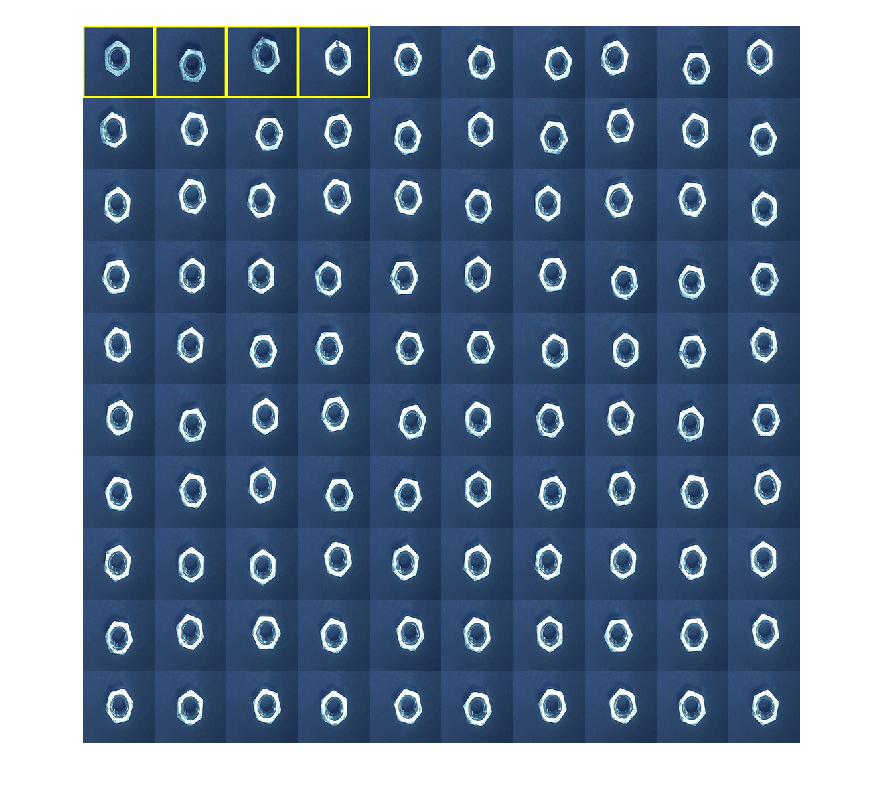

im = readall(imds2);
im = im(idx); % sort images by score in ascending order
sz = size(im{1});
% Insert rectangle on images people defined as anomaly
for i=1:numel(idx)
    if idx(i) < 5
        im{i} = insertShape(uint8(im{i}),'rectangle',[1 1 sz(1) sz(2)],'LineWidth' ,10);
    end
end
I = cat(4, im{1:100}); 
figure,montage(I, 'Size', [10 10]) % show 10*10 images in a figure

% The score of images in the first row are low. (anomalousness is high) 
% the 1-4 lowest score images have rectangle yellow frame.
% This means that prediction by classifier is same as the correct answer people define.
score(idx) %

ans = 100×1 single column vector
   -2.3860
   -2.3368
   -2.2854
   -1.1663
   -0.7613
   -0.6586
   -0.6303
   -0.5087
   -0.4596
   -0.4513


Use t-SNE for visualization

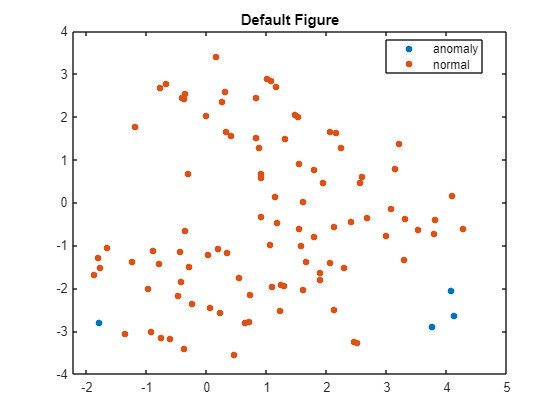

rng default % 
testLabels = imds2.Labels; % Use label for visualization 
% Use t-SNE to visualize 4096 dimension data bidimensionally
Y = tsne(testFeatures','Algorithm','exact','NumPCAComponents',50,'Perplexity',45);
figure
gscatter(Y(:,1),Y(:,2),testLabels)
title('Default Figure')

% feature plots of abnormal image are located far from center of whole distribution
% classifier detects these outliers